%% demo_CA_loaded.mlx
clear; clc; close all;

%% ===================== Reproducibility note =====================
% This script evaluates four controllers under the same CA closed-loop setup:
%
%   Opt:
%       The teacher QP controller. It is rebuilt here from the public CA
%       allocation model, hard interface, and quadratic objective.
%
%   Cert:
%       The proposed certified executor. The offline certified-library
%       construction, active-library completion, and training toolbox are
%       not included in this release. A prebuilt deployment object is loaded.
%
%   NN:
%       A pure neural-network baseline. For exact closed-loop reproduction,
%       this script uses the saved NNDeploy weights.
%
%   NN+Proj:
%       The same NN followed by a Euclidean projection onto
%       S*x + G*du <= h whenever the NN output violates the hard interface.
%
% The released XTrain and YTrain are included for transparency and optional
% retraining of public baselines. The default closed-loop run does not retrain.

%% ===================== Initialization =====================
rng(2);

%% ===================== Load release package =====================
release_mat = 'demo_CA_release_pack.mat';
load(release_mat, 'problem', 'qp_cfg', 'train_data', 'cert_info', 'nn_info', 'sim_cfg', 'plot_cfg', 'ctrl');

G         = problem.G;
S         = problem.S;
h         = problem.h;
B         = problem.B;
nu        = problem.nu;
nw        = problem.nw;
Ts        = problem.Ts;
Ts_us     = problem.Ts_us;
eps_feas  = problem.eps_feas;
u_min     = problem.u_min;
u_max     = problem.u_max;
du_max    = problem.du_max;
beta      = problem.beta;

OPCert    = ctrl.OPCert;
NNDeploy  = ctrl.NNDeploy;

OPCert.mex_ready = false;
OPCert.mex_id    = [];

nTest     = sim_cfg.nTest;
Utest_ref = sim_cfg.Utest_ref;
WdesTest  = sim_cfg.WdesTest;
x0        = sim_cfg.x0;
wd0       = sim_cfg.wd0;
name      = sim_cfg.name;
nMethod   = sim_cfg.nMethod;

maxNumCompThreads(sim_cfg.maxNumCompThreads);

fprintf(['\n==================== CA LOADED DEMO ====================\n' ...
         '[Load] %s\n' ...
         '[Data] XTrain = %d-by-%d, YTrain = %d-by-%d\n' ...
         '[Cert] nLaw = %d, nAct = %d, cover = %s\n' ...
         '[NN] train_mse_scaled = %.3e, train_mse_raw = %.3e\n'], ...
         release_mat, ...
         size(train_data.XTrain, 1), size(train_data.XTrain, 2), ...
         size(train_data.YTrain, 1), size(train_data.YTrain, 2), ...
         cert_info.nLaw, cert_info.nAct, cert_info.cover_status, ...
         nn_info.nn_train_mse_scaled, nn_info.nn_train_mse_raw);


==================== CA LOADED DEMO ====================
[Load] demo_CA_release_pack.mat
[Data] XTrain = 9-by-20000, YTrain = 6-by-20000
[Cert] nLaw = 4096, nAct = 353, cover = certified
[NN] train_mse_scaled = 3.268e-02, train_mse_raw = 3.268e-04



%% ===================== Rebuild public Opt baseline =====================
ops = sdpsettings('solver', qp_cfg.solver, 'verbose', 0);

x  = sdpvar(nu, 1);
wd = sdpvar(nw, 1);
du = sdpvar(nu, 1);

C = G * du <= h - S * x;
J = (B * (x + du) - wd)' * (B * (x + du) - wd) + beta * (du' * du);

OPbase_ca = optimizer(C, J, ops, {x, wd}, du);

%% ===================== Rebuild public NN+Proj baseline =====================
x_proj     = sdpvar(nu, 1);
du_nn_proj = sdpvar(nu, 1);
du_proj    = sdpvar(nu, 1);

Cproj      = S * x_proj + G * du_proj <= h;
Jproj      = (du_proj - du_nn_proj)' * (du_proj - du_nn_proj);
OPproj_ca  = optimizer(Cproj, Jproj, ops, {x_proj, du_nn_proj}, du_proj);


%% ===================== Initialize deployed NN and warm-up =====================
nn_policy_mex('clear');
nn_policy_mex('init', NNDeploy);

for i = 1:200
    OPbase_ca{x0, wd0};
    OPCert.cert_forward(x0, wd0);

    du_nn0 = nn_policy_mex('eval', [x0; wd0]);

    if max([0; S * x0 + G * du_nn0 - h]) > eps_feas
        OPproj_ca{x0, du_nn0};
    end
end

du0_opt  = OPbase_ca{x0, wd0};
du0_cert = OPCert.cert_forward(x0, wd0);
du0_nn   = nn_policy_mex('eval', [x0; wd0]);

if max([0; S * x0 + G * du0_nn - h]) > eps_feas
    du0_proj = OPproj_ca{x0, du0_nn};
else
    du0_proj = du0_nn;
end

v0_opt  = max([0; S * x0 + G * double(du0_opt) - h]);
v0_cert = max([0; S * x0 + G * double(du0_cert) - h]);
v0_nn   = max([0; S * x0 + G * double(du0_nn) - h]);
v0_proj = max([0; S * x0 + G * double(du0_proj) - h]);

fprintf(['[Warm-up] Opt     max_violation = %.3e\n' ...
         '[Warm-up] Cert    max_violation = %.3e\n' ...
         '[Warm-up] NN      max_violation = %.3e\n' ...
         '[Warm-up] NN+Proj max_violation = %.3e\n'], ...
         v0_opt, v0_cert, v0_nn, v0_proj);

[Warm-up] Opt     max_violation = 0.000e+00
[Warm-up] Cert    max_violation = 0.000e+00
[Warm-up] NN      max_violation = 0.000e+00
[Warm-up] NN+Proj max_violation = 0.000e+00


%% ===================== Closed-loop test =====================
time_us       = nan(nTest, nMethod);
miss_traj     = false(nTest, nMethod);
proj_trigger  = false(nTest, 1);
du_raw_traj   = nan(nTest, nu, nMethod);
du_cmd_traj   = nan(nTest, nu, nMethod);
raw_viol_traj = nan(nTest, nMethod);
track_traj    = nan(nTest, nMethod);
x_traj        = nan(nTest + 1, nu, nMethod);
w_traj        = nan(nTest, nw, nMethod);

for j = 1:nMethod
    x_traj(1, :, j) = x0.';
end

for k = 1:nTest
    wdk = WdesTest(:, k);

    for j = 1:nMethod
        xk = x_traj(k, :, j).';

        t0 = tic;

        if j == 1
            du_raw = double(OPbase_ca{xk, wdk});
        elseif j == 2
            du_raw = double(OPCert.cert_forward(xk, wdk));
        elseif j == 3
            du_raw = double(nn_policy_mex('eval', [xk; wdk]));
        else
            du_nn           = double(nn_policy_mex('eval', [xk; wdk]));
            proj_hit        = max([0; S * xk + G * du_nn - h]) > eps_feas;
            proj_trigger(k) = proj_hit;

            if proj_hit
                du_raw = double(OPproj_ca{xk, du_nn});
            else
                du_raw = du_nn;
            end
        end

        time_us(k, j)   = 1e6 * toc(t0);
        miss_traj(k, j) = time_us(k, j) > Ts_us;

        if miss_traj(k, j)
            du_cmd = zeros(nu, 1);
        else
            du_cmd = du_raw;
        end

        x_next = min(max(xk + du_cmd, u_min), u_max);

        du_raw_traj(k, :, j)   = du_raw.';
        du_cmd_traj(k, :, j)   = du_cmd.';
        raw_viol_traj(k, j)    = max([0; S * xk + G * du_raw - h]);
        track_traj(k, j)       = sum((B * x_next - wdk).^2);
        x_traj(k + 1, :, j)    = x_next.';
        w_traj(k, :, j)        = (B * x_next).';
    end
end


%% ===================== Report =====================
tOpt_mean        = mean(time_us(:, 1), 'omitnan');
opt_timeout_rate = mean(miss_traj(:, 1), 'omitnan');
proj_rate        = mean(proj_trigger, 'omitnan');

fprintf(['\n==================== CA LOADED REPORT ====================\n' ...
         'Ts = %.0fus, nTest = %d, eps_feas = %.1e\n' ...
         'zero increment is applied on deadline miss\n' ...
         'Opt timeout rate = %.2f%%\n' ...
         'NN+Proj projection rate = %.2f%%\n' ...
         '-------------------------------------------------------------------------------------------------------\n' ...
         '%-9s | %-22s | %-8s | %-9s | %-8s | %-8s | %-10s\n' ...
         '-------------------------------------------------------------------------------------------------------\n'], ...
         Ts_us, nTest, eps_feas, 100 * opt_timeout_rate, 100 * proj_rate, ...
         'Method', 'time_us mean/p50/p99', 'speedup', 'max viol.', 'viol.', 'miss', 'wRMSE');


==================== CA LOADED REPORT ====================
Ts = 1000us, nTest = 500, eps_feas = 1.0e-04
zero increment is applied on deadline miss
Opt timeout rate = 26.00%
NN+Proj projection rate = 37.60%
-------------------------------------------------------------------------------------------------------
Method    | time_us mean/p50/p99   | speedup  | max viol. | viol.    | miss     | wRMSE     
-------------------------------------------------------------------------------------------------------



for j = 1:nMethod
    tj          = time_us(:, j);
    tj_finite   = tj(isfinite(tj));
    t_mean      = mean(tj, 'omitnan');
    t_p50       = prctile(tj_finite, 50);
    t_p99       = prctile(tj_finite, 99);
    speedup_opt = tOpt_mean / max(t_mean, eps);

    vj          = raw_viol_traj(:, j);
    max_viol    = max(vj, [], 'omitnan');
    viol_rate   = mean(vj > eps_feas, 'omitnan');
    miss_rate   = mean(miss_traj(:, j), 'omitnan');
    wrmse       = sqrt(mean(track_traj(:, j), 'omitnan'));

    fprintf('%-9s | %7.1f/%6.1f/%6.1f | %7.2fx | %9.2e | %6.2f%% | %6.2f%% | %10.3e\n', ...
        name{j}, t_mean, t_p50, t_p99, speedup_opt, max_viol, 100 * viol_rate, 100 * miss_rate, wrmse);
end

Opt       |  1006.3/ 904.1/2027.4 |    1.00x |  1.04e-05 |   0.00% |  26.00% |  2.098e-01
Cert      |    63.3/  52.0/ 185.8 |   15.89x |  0.00e+00 |   0.00% |   0.00% |  4.231e-02
NN        |    10.1/   8.0/  32.2 |   99.97x |  3.12e-02 |  48.60% |   0.00% |  3.097e-01
NN+Proj   |   387.2/   7.1/1885.3 |    2.60x |  5.31e-12 |   0.00% |  10.40% |  3.222e-01



fprintf(['-------------------------------------------------------------------------------------------------------\n' ...
         'wRMSE = sqrt(mean_k ||B u_{k+1} - w_{d,k}||_2^2). It is not normalized by Opt because deadline misses change the deployed Opt rollout.\n']);

-------------------------------------------------------------------------------------------------------
wRMSE = sqrt(mean_k ||B u_{k+1} - w_{d,k}||_2^2). It is not normalized by Opt because deadline misses change the deployed Opt rollout.


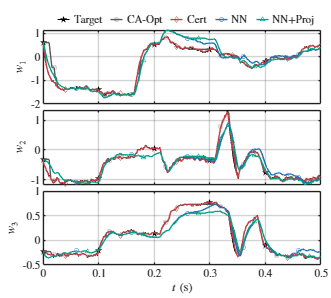

%% ===================== Plot =====================
t_step = (0:nTest - 1) * Ts;

fig_w_in = plot_cfg.fig_w_in;
fig_h_in = plot_cfg.fig_h_in;
fs       = plot_cfg.fs;
% lw       = plot_cfg.lw;
% lw_ref   = plot_cfg.lw_ref;
lw     = 0.4;
lw_ref = 0.8;
ms       = plot_cfg.ms;
clr      = plot_cfg.clr;
mk       = plot_cfg.mk;

plot_name = plot_cfg.plot_name;

mk_step  = max(nMethod + 1, round(nTest / 5));
mk_base  = 1:mk_step:nTest;
mk_shift = round((1:nMethod) / (nMethod + 1) * mk_step);

fig = figure('Color', 'w', 'Units', 'inches', 'Position', [1, 1, fig_w_in, fig_h_in], 'Renderer', 'painters');

pos = [
    0.13 0.65 0.84 0.25
    0.13 0.38 0.84 0.25
    0.13 0.11 0.84 0.25
];

ax    = gobjects(nw, 1);
h_leg = gobjects(nMethod + 1, 1);

for i = 1:nw
    ax(i) = axes('Position', pos(i, :));
    hold(ax(i), 'on'); grid(ax(i), 'on');

    h_ref = plot(ax(i), t_step, WdesTest(i, :), 'k-', ...
        'LineWidth', lw_ref, ...
        'Marker', 'p', ...
        'MarkerSize', ms);

    h_ref.MarkerIndices = mk_base;

    if i == 1
        h_leg(1) = h_ref;
    else
        h_ref.HandleVisibility = 'off';
    end

    for j = 1:nMethod
        hp = plot(ax(i), t_step, w_traj(:, i, j), ...
            'LineWidth', lw, ...
            'Color', clr(j, :), ...
            'Marker', mk{j}, ...
            'MarkerSize', ms, ...
            'MarkerFaceColor', 'none', ...
            'MarkerEdgeColor', clr(j, :));

        id = mk_base + mk_shift(j);
        hp.MarkerIndices = id(id <= nTest);

        if i == 1
            h_leg(j + 1) = hp;
        else
            hp.HandleVisibility = 'off';
        end
    end

    ylabel(ax(i), sprintf('$w_%d$', i), 'Interpreter', 'latex');

    if i < nw
        set(ax(i), 'XTickLabel', []);
    else
        xlabel(ax(i), '$t\;(\mathrm{s})$', 'Interpreter', 'latex');
    end
end

lgd = legend(ax(1), h_leg, [{'Target'}, plot_name], ...
    'Interpreter', 'latex', ...
    'Orientation', 'horizontal', ...
    'Location', 'northoutside', ...
    'Box', 'off');
set(lgd, 'FontSize', fs, 'LineWidth', 0.5);
try, lgd.NumColumns = nMethod + 1; catch, end
try, lgd.ItemTokenSize = [9, 7]; catch, end

lgd.Units = 'normalized';
lgd.Position = [0.16, 0.90, 0.82, 0.07];

set(ax, ...
    'FontSize', fs, ...
    'TickLabelInterpreter', 'latex', ...
    'LineWidth', 0.7, ...
    'Box', 'on', ...
    'XMinorGrid', 'off', ...
    'YMinorGrid', 'off', ...
    'GridAlpha', 0.20);

%% ===================== Export figure =====================
pdf_name = 'sim_CA.pdf';

set(fig, ...
    'Renderer', 'painters', ...
    'PaperUnits', 'inches', ...
    'PaperPosition', [0, 0, fig_w_in, fig_h_in], ...
    'PaperSize', [fig_w_in, fig_h_in]);

drawnow;
exportgraphics(fig, pdf_name, 'ContentType', 'vector');


fprintf('[Plot] saved PDF: %s\n', pdf_name);

[Plot] saved PDF: sim_CA.pdf
